# Performance evaluation: holdout

The data in "exam_bloods_clean.csv" has been cleaned and is ready for use in machine learning tasks:

clear all;
data = readtable('exam_bloods_clean.csv');

You hope to predict the "diagnosis" feature. Split the data and use it to evaluate the performance of a classifier of your choice using a simple holdout approach with 20% of the data reserved for testing and the other 80% used for training.

Marks are available for:

- Splitting the data up into an appropriately sized training dataset and testing dataset [8 marks]

- Appropriate calls to train and test the classifier [4 marks]

- Computing the area under the Receiver Operating Characteristic (ROC) curve for the classifier, taking "diseased" as the positive class [4 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:
%display summary of data
summary(data);

Variables:

    age: 583×1 double

        Values:

            Min           4   
            Median       45   
            Max          90   

    tot_bilirubin: 583×1 double

        Values:

            Min         0.4   
            Median        1   
            Max          75   

    direct_bilirubin: 583×1 double

        Values:

            Min          0.1  
            Median       0.3  
            Max         19.7  

    tot_proteins: 583×1 double

        Values:

            Min           63  
            Median       208  
            Max         2110  

    albumin: 583×1 double

        Values:

            Min           10  
            Median        35  
            Max         2000  

    ag_ratio: 583×1 double

        Values:

            Min           10  
            Median        42  
            Max         4929  

    sgpt: 583×1 double




%calculate number of examples used for 20% by multiplying original size by 0.2 and rounding:
nTest = round(0.20 * size(data,1));

% re-seed Matlab's random number generator:
rng(1)

% shuffle the data (using randperm) and create a testing dataset and a training dataset:
data_shuffled = data(randperm(size(data,1)), :);
data_test = data_shuffled(1:1:nTest, :); %create testing set
size(data_test);
data_train = data_shuffled(nTest+1:1:end, :); %create training set
size(data_train);

% separate the examples and the labels for the testing dataset:
test_labels = categorical(data_test{:,'diagnosis'});
test_examples = data_test;
test_examples(:,'diagnosis') = [];
% separate the examples and the labels for the training dataset:
train_labels = categorical(data_train{:,'diagnosis'});
train_examples = data_train;
train_examples(:,'diagnosis') = [];

% train a Decision Tree classifier from the training data:
m = fitctree(train_examples, train_labels, 'MergeLeaves', 'off', 'Prune', 'off')

m =   ClassificationTree
           PredictorNames: {'age'  'tot_bilirubin'  'direct_bilirubin'  'tot_proteins'  'albumin'  'ag_ratio'  'sgpt'  'sgot'  'alkphos'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [diseased    healthy]
           ScoreTransform: 'none'
          NumObservations: 466


  Properties, Methods


%m = fitcknn(train_examples, train_labels, 'NumNeighbors', 15, 'Standardize', true)

% use our trained Decision Tree classifier to classify the testing data:
[predictions, scores] = predict(m, test_examples);

% output a confusion matrix:
[c,order] = confusionmat(test_labels, predictions)

c =     15    16
    18    68


order = 2×1 categorical array
     diseased 
     healthy 


%calculate overall classification accuracy
p = sum(diag(c)) / sum(c(1:1:end))

p = 0.7094


%create ROC curve
[x,y,~,AUC] = perfcurve(test_labels, scores(:, 1), m.ClassNames(1)); %giving 'diseased' as positive class 
AUC %output area under curve

AUC = 0.6386

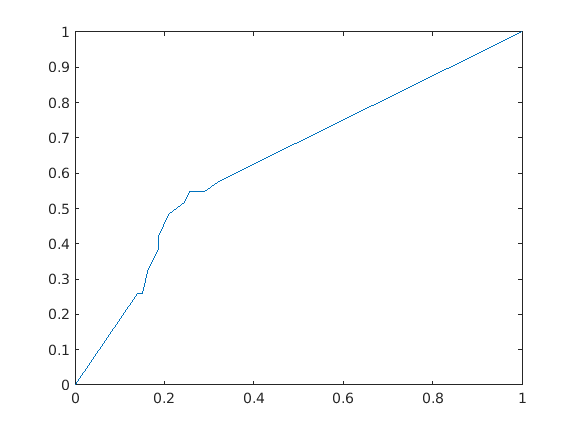

plot(x,y)%plot x and y given from perfcurve to display ROC curve